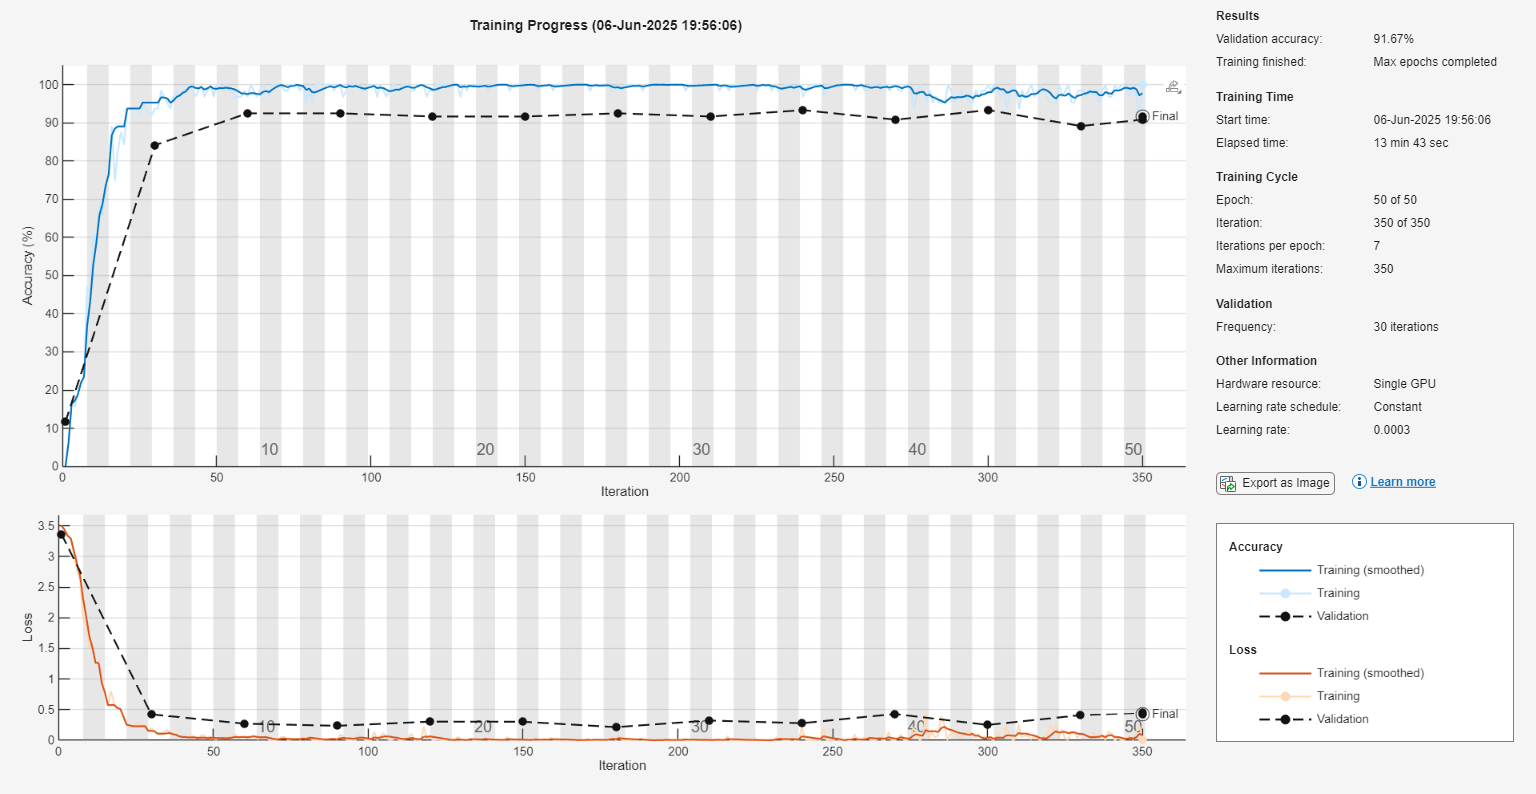

%% ASL Classification - Using MobileNetV2 for Better Accuracy
clc; clear; close all;

%% Step 1: Define Paths
trainFolder     = "D:\Coursera\Data\MathWorks Created\ASL Alphabet\Classification\Train";
testFolder      = "D:\Coursera\Data\MathWorks Created\ASL Alphabet\Classification\Test";

%% Step 2: Load and Split Data
imds = imageDatastore(trainFolder, 'IncludeSubfolders', true, 'LabelSource', 'foldernames');
[imdsTrain, imdsVal] = splitEachLabel(imds, 0.8, 'randomized');

imageAugmenter = imageDataAugmenter( ...
    'RandRotation', [-15 15], ...
    'RandXTranslation', [-4 4], ...
    'RandYTranslation', [-4 4], ...
    'RandXReflection', true, ...
    'RandXScale', [0.8 1.2], ...
    'RandYScale', [0.8 1.2]);

augTrain = augmentedImageDatastore([224 224], imdsTrain, ...
    'DataAugmentation', imageAugmenter, ...
    'ColorPreprocessing','gray2rgb');

augVal = augmentedImageDatastore([224 224], imdsVal, ...
    'ColorPreprocessing','gray2rgb');

%% Step 3: Load MobileNetV2 and Modify
net = mobilenetv2;
lgraph = layerGraph(net);

numClasses = 24;

% Replace final layers
lgraph = removeLayers(lgraph, {'Logits','Logits_softmax','ClassificationLayer_Logits'});

newLayers = [
    fullyConnectedLayer(numClasses, 'Name', 'fc_asl', ...
        'WeightLearnRateFactor', 10, 'BiasLearnRateFactor', 10)
    softmaxLayer('Name','softmax')
    classificationLayer('Name','output')];

lgraph = addLayers(lgraph, newLayers);
lgraph = connectLayers(lgraph, 'global_average_pooling2d_1', 'fc_asl');

%% Step 4: Test Data
imdsTest = imageDatastore(testFolder, "IncludeSubfolders", true, "LabelSource", "foldernames");
augTest  = augmentedImageDatastore([224 224], imdsTest, 'ColorPreprocessing','gray2rgb');

%% Step 5: Training on GPU
options = trainingOptions('adam', ...
    'MiniBatchSize', 64, ...
    'MaxEpochs', 50, ...
    'InitialLearnRate', 3e-4, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', augVal, ...
    'ValidationFrequency', 30, ...
    'ExecutionEnvironment', 'gpu', ...
    'Plots', 'training-progress', ...
    'Verbose', false);

trainedNet = trainNetwork(augTrain, lgraph, options);


%% Step 6: Evaluation
YPred = classify(trainedNet, augTest);
YTrue = imdsTest.Labels;

testAccuracy = mean(YPred == YTrue);
fprintf('\n✅ Test Accuracy: %.2f%%\n', testAccuracy * 100);


✅ Test Accuracy: 90.42%


%% Step 1: Define Test Folder Path
testFolder = fullfile('D:\Coursera', 'Data', 'MathWorks Created', ...
    'ASL Alphabet', 'Classification', 'Test');

%% Step 2: Load Test Dataset
imdsTest = imageDatastore(testFolder, ...
    'IncludeSubfolders', true, ...
    'LabelSource', 'foldernames');

% Resize and preprocess (assuming training used 224x224 RGB images)
augTest = augmentedImageDatastore([224 224], imdsTest, ...
    'ColorPreprocessing', 'gray2rgb');

%% Step 3: Load Your Trained Model
% If you have a saved model, load it like this:
% load('trainedASLNet.mat', 'trainedNet');

% Otherwise, assume 'trainedNet' is already in the workspace

%% Step 4: Classify Test Images
YPred = classify(trainedNet, augTest);
YTrue = imdsTest.Labels;

%% Step 5: Accuracy Calculation
accuracy = mean(YPred == YTrue);
fprintf('Final Test Accuracy: %.2f%%\n', accuracy * 100);

Final Test Accuracy: 90.42%



%% Step 6: Confusion Matrix (Optional)
figure;
confusionchart(YTrue, YPred);
title('Confusion Matrix - Test Set');

%% Paths
unlabeledFolder = "D:\Coursera\Data\MathWorks Created\ASL Alphabet\Classification\Unlabeled";
modelPath = 'trainedASLModel.mat';  % Optional: if saved previously

%% Load the trained model (skip if already in workspace)
% load(modelPath);  % Uncomment if you saved your model earlier

% Make sure your model is named `trainedNet`
% If you've trained it just before, it's already in your workspace.

%% Load Unlabeled Images
imdsUnlabeled = imageDatastore(unlabeledFolder);
augUnlabeled = augmentedImageDatastore([224 224], imdsUnlabeled, 'ColorPreprocessing','gray2rgb');

%% Predict Labels for Unlabeled Images
[YPred, scores] = classify(trainedNet, augUnlabeled);

%% Display Predictions with Confidence
figure('Name', 'ASL Unlabeled Predictions');
for i = 1:numel(imdsUnlabeled.Files)
    img = readimage(imdsUnlabeled, i);
    label = YPred(i);
    confidence = max(scores(i, :)) * 100;

    subplot(3, 3, i);
    imshow(img);
    title(sprintf('%s (%.1f%%)', string(label), confidence), 'FontSize', 12);
end

%% Show Final Predicted Message
predictedMessage = join(string(YPred), '');
fprintf('\nPredicted ASL Message: %s\n', predictedMessage);

testASLmodel(trainedNet);


%% Step 9: Run Grader (if accuracy ≥ 90%)
addpath(graderPath);

if accuracy >= 0.90
    fprintf('\nRunning testASLmodel grader...\n');
    testASLmodel(trainedNet);  % Show final code
else
    fprintf('\nModel accuracy is below 90%%. Try improving the network.\n');
end
